clear
targetImage = im2double(imread("dogdogorange.png"));
targetImage = imresize(targetImage, 0.25);
load("M_XYZ2RGB.mat")
quantizeLevel = 30;
histColours = reshape(targetImage(1, 1, :),[3, 1]);
histColours(4,1) = 0;
[rMax, cMax, dMax] = size(targetImage);
for r = 1:rMax
    for c = 1:cMax
        [~, histLength] = size(histColours);
        currentColour = reshape(targetImage(r, c, :),[3, 1]);
        currentColourXYZ = inv(M_XYZ2RGB) * currentColour;
        currentColourXYZ = quantizeColour(currentColourXYZ, quantizeLevel);
        colourFound = false;
        for i = 1:histLength
            compareColour = reshape(histColours(1:3,i),[3, 1]);
            compareColourXYZ = inv(M_XYZ2RGB) * compareColour;
            compareColourXYZ = quantizeColour(compareColourXYZ, quantizeLevel);
            [meanDeltaE, Max] = calcDeltaE(currentColourXYZ', compareColourXYZ');
            
            % if same inc counter
            if meanDeltaE < quantizeLevel
                histColours(4,i) = histColours(4,i) + 1;
                colourFound = true;
                break
            end
        end
        % if we have not found the colour add it
        if colourFound == false
            histColours(1:3, end+1) = currentColour;
            histColours(4, end) = 1;
        end
    end
end

[~, histLength] = size(histColours);
histColours(4,:)

ans =        26922         865        1797        5627        1498         169          75        1150          76           8           4           1


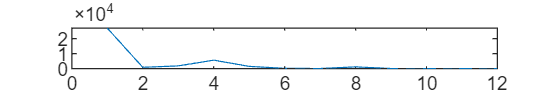

plot(histColours(4,:))

numberOfWantedColours = 10;
mostCommonColours = zeros(3, numberOfWantedColours);
for c = 1:numberOfWantedColours
    maxValue = 0;
    bestIndex = 1;
    for i = 1:histLength
        if histColours(4,i) > maxValue
            maxValue = histColours(4,i);
            bestIndex = i;
        end
    end
    histColours(4, bestIndex) = 0;
    mostCommonColours(:, c) = histColours(1:3, bestIndex);
end

mostCommonColours

mostCommonColours =     0.7193    0.2106    0.5899    0.4152    0.3298    0.5833    0.9704    0.2991    0.3053    0.0476
    0.6281    0.1888    0.6153    0.3640    0.3051    0.6001    0.9149    0.2872    0.3010    0.0017
    0.5512    0.1323    0.5860    0.2605    0.2437    0.5830    0.7655    0.2916    0.2842   -0.0061


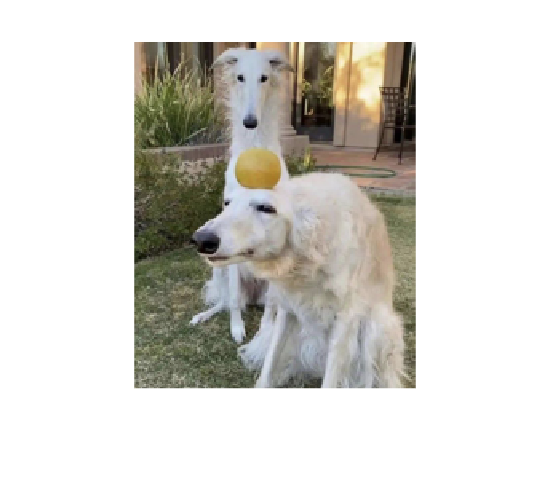

%histColours(1, :)
imshow(targetImage)

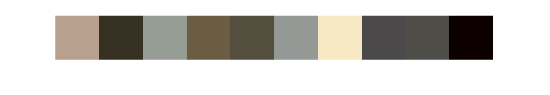

showRGB(mostCommonColours')

ans =       421896       29819       13579       18423       95730       23126        1239        2764        1179           8           4


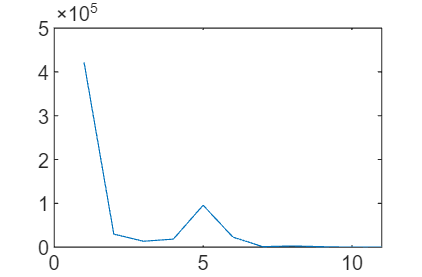

colours =     0.7176    0.2549    0.7137    0.4157    0.2824    0.5882    0.9765    0.3216    0.2980    0.3804
    0.6314    0.2706    0.5961    0.3686    0.3098    0.6039    0.9569    0.3137    0.2941    0.2784
    0.5569    0.2275    0.4784    0.2588    0.2706    0.5882    0.8275    0.2706    0.3137    0.2471
    0.6942    0.1575    0.0491    0.0381    0.0303    0.0223    0.0045    0.0020    0.0019    0.0000


targetImage = im2double(imread("dogdogorange.png"));
colours = getImportantColours(targetImage, 10)

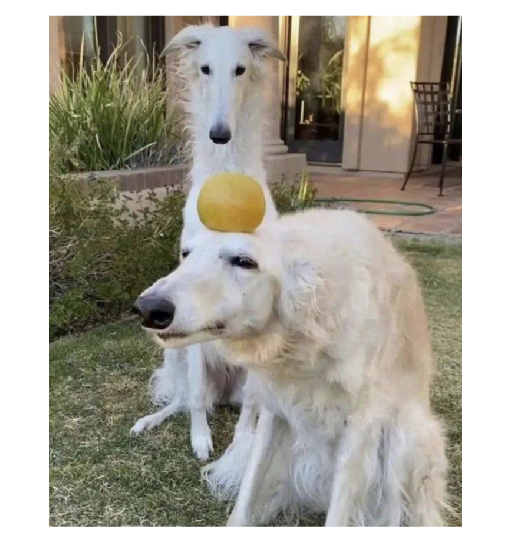

imshow(targetImage)

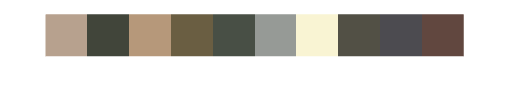

showRGB(colours')

colours(4,:)

ans =     0.6942    0.1575    0.0491    0.0381    0.0303    0.0223    0.0045    0.0020    0.0019    0.0000


ans =        45185         153       48224         111


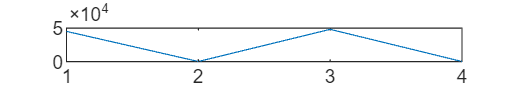

colours2 =     0.2588    1.0000
    0.2902    0.9490
    0.7882         0
    0.5148    0.4824



compareImage = im2double(imread("yellowBlue.png"));
colours2 = getImportantColours(compareImage, 2)

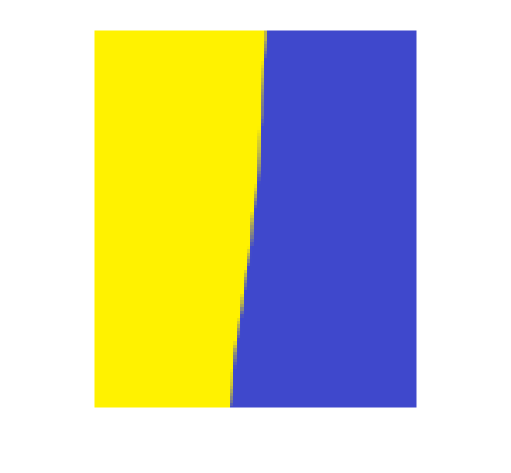

imshow(compareImage)

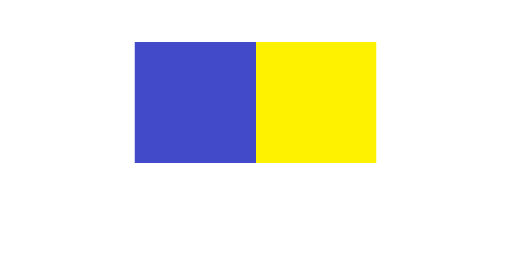

showRGB(colours2')

colours2(4,:)

ans =     0.5148    0.4824


colours2 = averageColourXYZ(compareImage)

colours2 =    54.3496
   59.3190
   47.5421


load("M_XYZ2RGB.mat");
colours2 = M_XYZ2RGB * colours2

colours2 =     0.6124
    0.6058
    0.4119


imshow(compareImage)

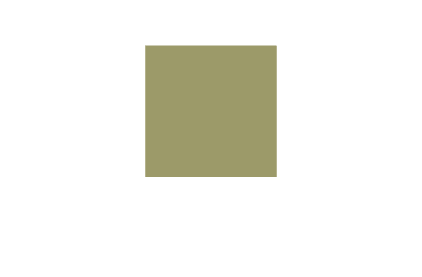

showRGB(colours2')


targetImage = targetImage(33:64, 33:64,:);
colours1 = averageColourXYZ(targetImage)

colours1 =    37.8843
   39.7238
   35.3840


load("M_XYZ2RGB.mat");
colours1 = M_XYZ2RGB * colours1

colours1 =     0.4406
    0.3927
    0.3141


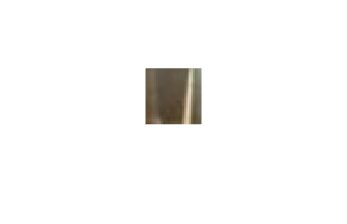

imshow(targetImage)

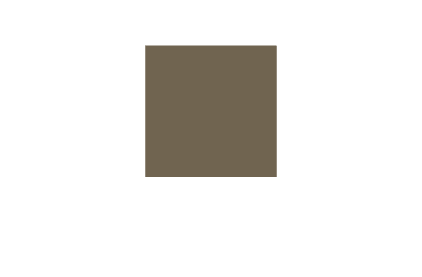

showRGB(colours1')